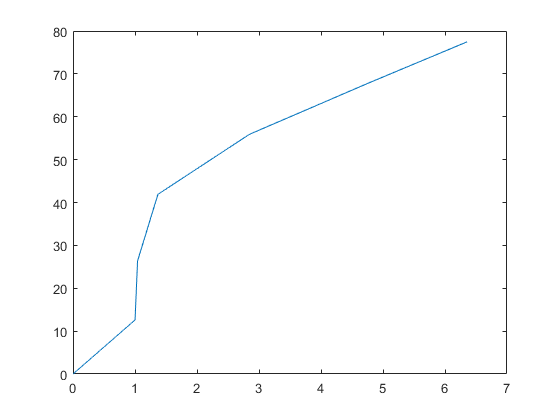

AudioFile = audioread('nuit04.wav')*128 + 128;
x= AudioFile;
%x=randl(1,1000000);s

delta = 0.03;
n=70;



SNR_arr = zeros(n,1);
BTR_arr = zeros(n,1);

for k = 1:n

    delta = delta + delta*k;

   q = round(x/delta);
   xhat = q*delta;
   D = mean((x-xhat).^2);
   sigma2 = mean(x.^2);
    SNR = 10*log10(sigma2/D);

file_prob = zeros(size(q,1),1);

for i = 2:size(q,1)
    file_prob(i,1) = q(i,1) - q(i-1,1);
end
file_prob = file_prob - min(file_prob)+1;

Yp1 = random_distribution(file_prob);

rate = huffman(Yp1);

SNR_arr(k) = SNR;
BTR_arr(k) = rate;
end

%probability and Huffman




plot(BTR_arr,SNR_arr)

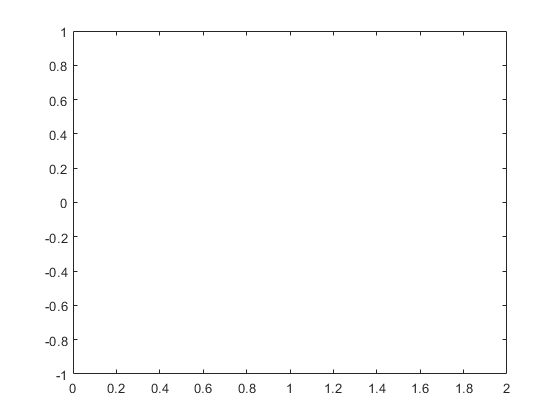

plot(SNR)